# Momentum and real space data analysis

Script for analyzing dispersion (k-space) and real-space energy profile (r-space) data in .spe files in a given folder.

% Clearing console, workspace and all figures
clc; clear; close all; fclose('all');

### Type of analysis

Choose in which space further analysis will be conducted. Only files with chosen string in theirs name will be analyze.

% Selection of space for analysis
% Chosen string has to be included in filename
space = "kspace";

### Measurement conditions

Specify conditions of a measurement, that will be analyze.

% Defining values of measurement conditions
% Objective and detector on our main setup: NA = 0.65, f = 4, dpx = 13
NA = 0.65;        % Numerical aperture [arb.u.]
f = 4;         % Focal length of the objective [mm]
dpx = 13;       % Pixel size [um]
magR = 37.5;      % R-space magnification [arb.u.]
magK = 1.06;      % K-space magnification [arb.u.]
px0 = 0;       % pixel for k0 [arb.u.]

### Files for analysis

Select if you want to analyze all files in a given folder or just one file. Folder with files for analysis should contain files to be analyze as well as background files with matching exposure times.

% Choosing folder with files to analyze and picking .spe files
file_or_folder = "file";
if file_or_folder == "folder"
    path = char("");
    path = strrep(path, '\\?\', '');
    files_to_analyze = dir(fullfile(path, '*.spe'));
elseif file_or_folder == "file"
    path = char("");
    path = strrep(path, '\\?\', '');
    path_to_extand = java.io.File(path);
    path = char(path_to_extand.getCanonicalPath());
    path_split =  split(path,"\");
    path_split = convertCharsToStrings(path_split);
    path = join(path_split(1:end-1), "\");
    file_name = path_split(end);
    files_to_analyze = dir(fullfile(path, '*.spe'));
end

% Choosing folder with neutral density filters transmission .xlsx files 
% and loading transmission data
ND_filters_path = char("");
ND_files = dir(fullfile(ND_filters_path, '*.xlsx'));
ND_filters = cell(size(ND_files, 1), 2);
for i = 1:size(ND_files, 1)
    ND_filter = readtable([ND_files(i).folder, '\', ...
        ND_files(i).name], 'VariableNamingRule', 'preserve');
    ND_filter = table2array(ND_filter(:,3:4));
    ND_filters(i, 1) = num2cell(str2double([ND_files(i).name(4), '.', ...
        ND_files(i).name(5)]));
    ND_filters(i, 2) = mat2cell(ND_filter, size(ND_filter, 1), ...
        size(ND_filter, 2));
end

% Preallocation of arrays sizes for files that are not for a given space
% and for background files
files_not_to_analyze = zeros(size(files_to_analyze));
background_files = zeros(size(files_to_analyze));

% Setting possible character strings
if space == "kspace"
    possible_space_strings = ["kspace", "k-space", "k_space", ...
        "momentumspace", "momentum-space", "momentum_space"];
elseif space == "rspace"
    possible_space_strings = ["rspace", "r-space", "r_space", ...
        "realspace", "real-space", "real_space"];
else
    disp("Unspecified space");
    return;
end

% Iterating through files to analyze to separate them from files not for
% the analysis and background files
for i = 1:size(files_to_analyze, 1)
    if contains(lower(files_to_analyze(i).name), ...
            possible_space_strings) == 0
        files_not_to_analyze(i) = i;
        if (contains(lower(files_to_analyze(i).name), 'bg') == 1 ...
                || contains(lower(files_to_analyze(i).name), ...
                'bck') == 1 ...
                || contains(lower(files_to_analyze(i).name), ...
                'background') == 1)
            background_files(i) = i;
        end
    end
end

% Deleting not used files and saving background files
files_not_to_analyze(files_not_to_analyze==0) = [];
background_files(background_files==0) = [];
background_files = files_to_analyze(background_files);
files_to_analyze(files_not_to_analyze) = [];

% Picking exact file to analyze
if file_or_folder == "file"
    for i = 1:size(files_to_analyze, 1)
        if files_to_analyze(i).name == file_name
            file_to_analyze = files_to_analyze(i);
        end
    end
    files_to_analyze = file_to_analyze;
end

% If there are no files to analyze terminate script
if size(files_to_analyze, 1) == 0
    disp("No files for the analysis. Check if proper space was chosen!");
    return;
end


### Analysis

Select tasks to be perform.

- Plot and save spectra graphs - Plotting spectra data and saving plotted figures in a folder inside chosen path e.g.:  .../ksapce_graphs.

- Figure visibility - If turned off no figures will appear as a script runs. If turned on all piloted figures will appear, so you can modify them.

- X-axis and Y-axis limits - Setting limiting values for x-axis and y-axis on spectra graphs.

- Extract points - Extracting points of high intensity and saving fit results in a folder inside chosen path: .../extracted_points for further analysis in another software such as OriginPro®. Works only for k-space data. 

- Extract points sensitivity - Setting responsible for the sensitivity of finding peaks. Lower values are recommended for cleaner data and higher value for more noisy and less visible data. With higher values there is higher risk of overfitting.

- Plot extracted points - Plotting extracted points onto the existing figures (Plot and save spectra graphs needs to be checked) and saving them. Extracted points need to be saved first (see Extract points). Works only for k-space data.

- Extract and plot energy distribution - Extracting the energy distribution from the extracted points, saving it in a folder inside chosen path: .../energy_distribution_points. Also plotting this distribution and saving plotted figures in a folder inside chosen path:  .../distribution_graphs. Works only for k-space data.

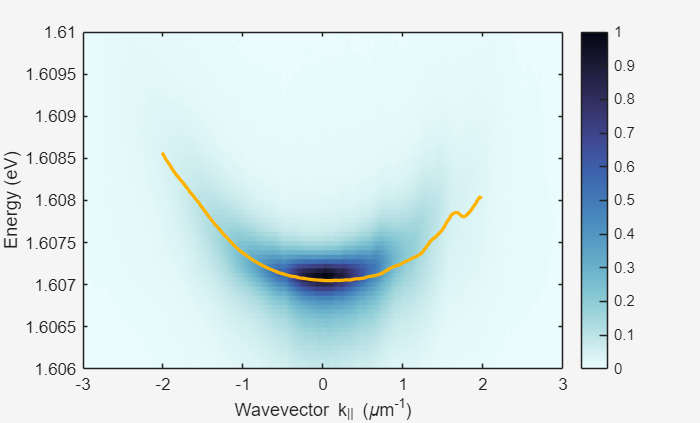

% Creating folders for graphs and extracted points (fitting results) and
% turning off the warning, that appears when those folders already exist
warning('off', 'MATLAB:MKDIR:DirectoryExists');
mkdir(files_to_analyze(1).folder, [char(space),'_graphs']);
mkdir(files_to_analyze(1).folder, 'extracted_points');
mkdir(files_to_analyze(1).folder, 'distribution_graphs');
mkdir(files_to_analyze(1).folder, 'energy_distribution_points');

% Creating progress bar
progress_bar = waitbar(0, ['Files', ' 0/', ...
    char(string(size(files_to_analyze, 1)))], 'Name', 'Analyzing files');

% Iterating through files to analyze
for i = 1:size(files_to_analyze, 1)

    % Reading data from 
    [x, energy, data] = read_SPE_file(files_to_analyze(i), ...
        background_files, ND_filters);
    
    % Shifting x-axis to have px0 as central pixel
    x = x - px0;
    
    % Changing pixel to wavevector or position depending on space
    if space == "kspace"
        [x, data] = pixel_to_wavevector(x, energy, data, NA, f, dpx, magK);
    elseif space == "rspace"
        [x, data] = pixel_to_position(x, data, NA, f, dpx, magK, magR);
    end
    
    % Performing trapezoidal transformation only for k-space data, which is
    % accounting for the energy dependence of the maximum imaging
    % wavevector
    if space == "kspace"
        [data] = trapezoidal_transformation(energy, data);
    end
    
    % Activation of plotting and saving graphs and changing figures
    % visibility
    plot_and_save_spectra_graphs = true;
    fig_visibility = "on";

    % Setting up x-axis and y-axis limits   
    custom_axis_limits = false;
    x_min = floor(min(x)*10000)/10000;
    x_max = ceil(max(x)*10000)/10000;
    x_axis_limits_default = [ceil(min(x)*10000)/10000 floor(max(x)*10000)/10000];
    x_axis_limits_control = [-5.3985 5.3985];
    y_min = floor(min(energy)*10000)/10000;
    y_max = ceil(max(energy)*10000)/10000;
    y_axis_limits_default = [ceil(min(energy)*10000)/10000 floor(max(energy)*10000)/10000];
    y_axis_limits_control = [1.5831 1.6388];
    if custom_axis_limits == 1
        x_axis_limits = x_axis_limits_control;
        y_axis_limits = y_axis_limits_control;
    else
        x_axis_limits = x_axis_limits_default;
        y_axis_limits = y_axis_limits_default;
    end
    
    % Plotting and saving graphs
    if plot_and_save_spectra_graphs == 1
        
        % Normalizing data
        normalized_data = reshape((data(:) - min(data(:))) ...
        / ( max(data(:)) - min(data(:)) ), [size(data,1), size(data,2)]);
        
        % Normalizing columns not whole data array
        % normalized_data = (data - min(data)) ./ (max(data) - min(data));

        % Drawing the graphs on a figure
        fig_space = draw_space_spectra(x, energy, normalized_data, space, ...
            fig_visibility, x_axis_limits, y_axis_limits);
        
        % Setting saving filename and deleting existing files to override
        % them
        saving_filename_space = files_to_analyze(i).folder + "\" + space ...
            + "_graphs" + "\" + ...
            string(files_to_analyze(i).name(1:end-4)) + ".jpeg";
        if exist(saving_filename_space, 'file') ~= 0
            delete(saving_filename_space);
        end

        % Exporting those figures to a folder in a given path
        exportgraphics(fig_space, saving_filename_space);
    end
    
    % Updating the waitbar to show which files out of how many is being
    % analyze
    waitbar(i/size(files_to_analyze, 1), progress_bar, ['Files ' ...
        char(string(i)), '/', char(string(size(files_to_analyze, 1)))]);
    
    % Performing points extraction only for k-space data
    extract_points = false;
    extract_points_sensitivity = 0.15;
    if (space == "kspace" && extract_points == 1)

        % Dividing data into branches
        [x, branches_energy, branches] = ...
            divide_data_into_branches(x, energy, data, files_to_analyze(i).folder(), files_to_analyze(i).name());
        
        % Extracting points from data by peak fitting
        extract_and_save_points(x, branches_energy, branches, ...
            files_to_analyze(i).folder, files_to_analyze(i).name(), ...
            extract_points_sensitivity);
    end

    % Performing points reading and drawing only for k-sapce data
    plot_extracted_points = false;
    if (space == "kspace" && plot_extracted_points == 1 && ...
            plot_and_save_spectra_graphs == 1)
        
        % Read and plot extracted points
        read_and_draw_points(fig_space , files_to_analyze(i));

        % Save modified figure
        exportgraphics(fig_space, saving_filename_space);
    end

    % Extracting and plotting energy distribution for k-space data
    extract_and_plot_energy_distribution = false;
    if (space == "kspace" && extract_and_plot_energy_distribution == 1)

        % Extracting and plotting energy distribution
        fig_distribution = extract_and_plot_distribution(files_to_analyze(i), ...
            fig_visibility);

        % Setting saving filename and deleting existing files to override
        % them
        saving_filename_distribution = files_to_analyze(i).folder + "\" + ...
            "distribution_graphs" + "\" + ...
            string(files_to_analyze(i).name(1:end-4)) + ".jpeg";
        if exist(saving_filename_distribution, 'file') ~= 0
            delete(saving_filename_distribution);
        end
        
        % Exporting figures to a folder in a given path
        exportgraphics(fig_distribution, saving_filename_distribution);
    end
end


% Updating progress bar to final message and closing it after short pause
waitbar(1, progress_bar, 'Analysis completed!');
pause(1);
close(progress_bar);